# Integrator Lab: Solving First Order ODEs in MATLAB and Picard Approximation

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first. This lab will also teach you how to manipulate symbolic functions in MATLAB.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures. You will also learn how to use MATLAB for exact symbolic calculations and write your own Picard approximation code.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are eight exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Blackboard.

MAT292, Fall 2018, Stinchcombe & Khovanskii MAT292, Fall 2017, Stinchcombe & Sinnamon MAT292, Fall 2015, Sousa MAT292, Fall 2013, Sinnamon & Sousa MAT292, Fall 2011, Hart & Pym

## Student Information

Student Name: Ruchir Tullu

Student Number: 1004220951

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`. 

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y;     

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]
          y: [1 1.2214 1.4918 1.8221 2.2255 2.7183 3.3201 4.0552 4.9530 6.0496 7.3891]
      stats: [1×1 struct]
      idata: [1×1 struct]



## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial vlaue problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



% Display the the corresponding approximatations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

    1.0000    1.2214    1.4918    1.8221    2.2255    2.7183    3.3201    4.0552    4.9530    6.0496    7.3891




% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));

 Third element of the vector of t values: 0.4


fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

 Third element of the vector of y values: 1.49182


## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

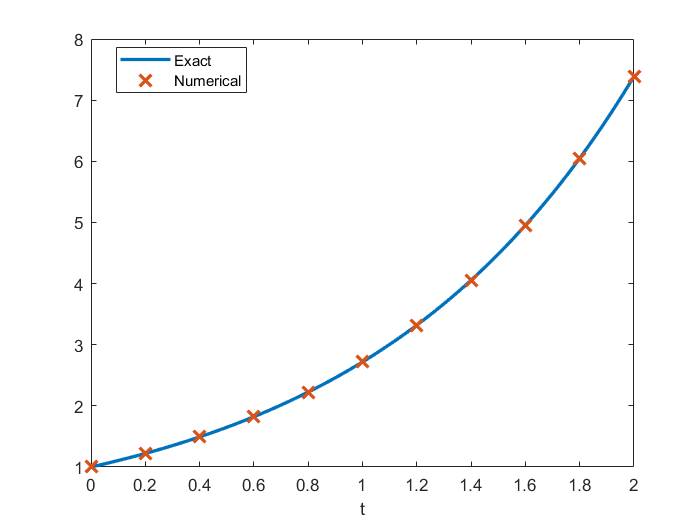

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Your submission should show the construction of the inline function, the use of ode45 to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

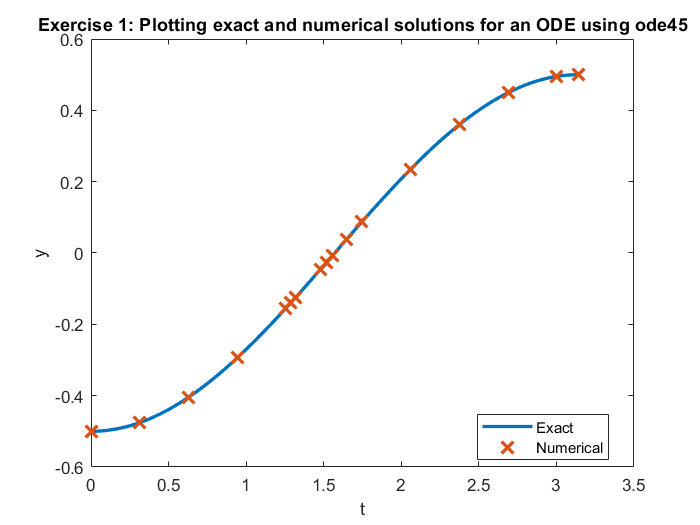

f = @(t,y) y*tan(t) + sin(t);

%Parameters
t0 = 0;     
t1 = pi;
y0 = -1/2;

soln1 = ode45( f, [t0,t1], y0);

%Exact solution plotting values
xx = linspace(0, pi, 100);
yy = (1/2).*(tan(xx).*sin(xx) - (1./(cos(xx))));        % Exact solution

% Exact solution;
% y = (1/2)* (tan(t)sin(t) - (1/cos(t)))

plot(xx, yy, soln1.x, soln1.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
title('Exercise 1: Plotting exact and numerical solutions for an ODE using ode45');
xlabel('t');
ylabel('y');
legend('Exact', 'Numerical', 'Location', 'Best');

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln1, .25)

ans = -0.4845


% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln1, 1.6753));

 Solution at 1.6753: 0.0521587



% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln1, tinterp)

ans =    -0.4502   -0.4173   -0.3770   -0.3300   -0.2771   -0.2193   -0.1577   -0.0932   -0.0271    0.0396



% Alternatively:
deval(soln1, linspace(.45, 1.65, 10))

ans =    -0.4502   -0.4173   -0.3770   -0.3300   -0.2771   -0.2193   -0.1577   -0.0932   -0.0271    0.0396


## Exercise 2

Objective: Interpolate a solution at a number of grid points

Details: For the solution you computed in exercise 1, use deval to compute the interpolated values at 10 grid points between 2 and 3.

Exercise2 = deval(soln1, linspace(2,3,10))

Exercise2 =     0.2081    0.2572    0.3032    0.3454    0.3833    0.4166    0.4447    0.4673    0.4841    0.4950


## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance. 

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln1.x);

% Compute the pointwise error; note the use of MATLAB's vectorization
err = abs(yexact - soln1.y);

disp(err);

    1.5000    1.8446    2.2790    2.8602    3.6681    3.7652    3.8658    4.4249    4.5882    4.7592    5.1634    5.6421    7.6088   10.3790   14.2530   19.6341   22.6407




fprintf('maximum error: %g \n', max(err));

maximum error: 22.6407 


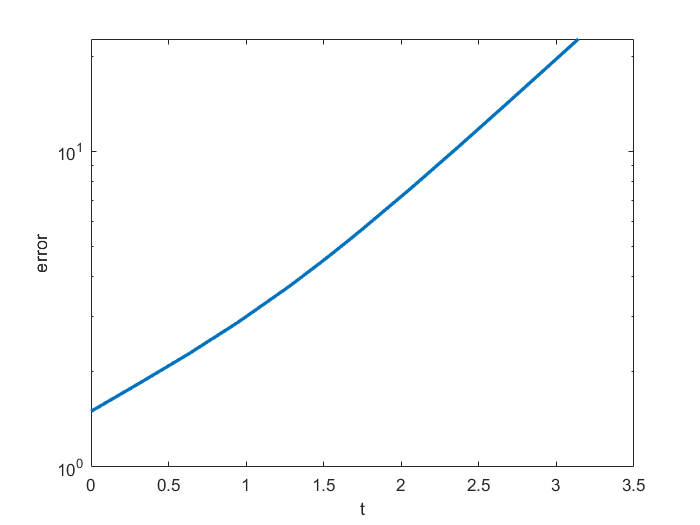


semilogy(soln1.x, err, 'LineWidth', 2);
xlabel('t');
ylabel('error');

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

Details: For your solution to exercise 1, compute the pointwise error, identify the maximum value of the error, and visualize the error on a linear-log plot (use semilogy to plot the log of the error vs. t). Write in the comments where the error is largest, and give a brief (1-2 sentences) explanation of why it is largest there. Make sure to label your axes.

% Retype solution to ensure correct usage of all variables
f = @(t,y) y*tan(t) + sin(t);

%Parameters
t0 = 0;     
t1 = pi;
y0 = -1/2;

soln3 = ode45( f, [t0,t1], y0);

%Exact solution plotting values
xx = linspace(0, pi, 100);
yy = (1/2).*(tan(xx).*sin(xx) - (1./(cos(xx))));        %Exact solution

% Exact solution;
% y = (1/2)* (tan(t)sin(t) - (1/cos(t)))


% Error:
yexact = (1/2).*(tan(soln3.x).*sin(soln3.x) - (1./(cos(soln3.x)))); 
err = abs(yexact - soln3.y);

fprintf('maximum error: %g \n', max(err));

maximum error: 1.8068e-05 


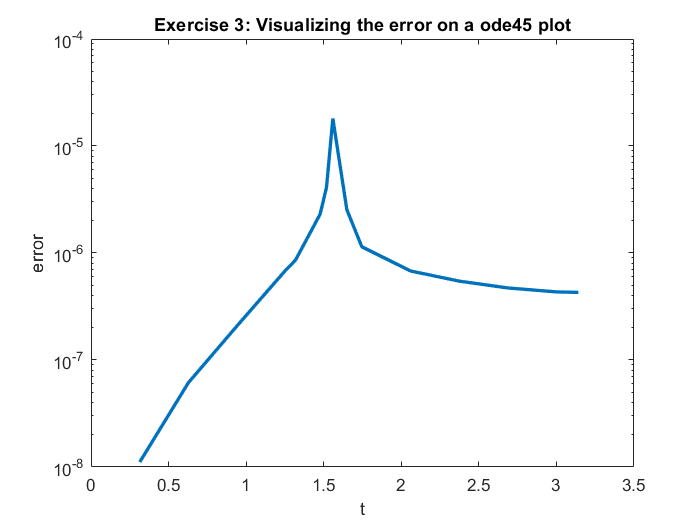


semilogy(soln3.x, err, 'LineWidth', 2);
title('Exercise 3: Visualizing the error on a ode45 plot')
xlabel('t');
ylabel('error');



% The error is max at a t-value of pi/2. This makes sense because at this point, (1/cos(pi/2)) is undefined. 
% The numerical approximation tries to find a value at this point, but due to the behaviour of the function at that point,
% (i.e. it tends to infinity) it results in a large error.



## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`

from `t=1` to `t=10` using `ode45`. Find the exact solution and compute the maximum pointwise error. Then plot the approximate solution and the exact solution on the same axes.

Your solution should show the definition of the inline function, the computation of its solution in this interval, the computation of the exact solution at the computed grid points, the computation of the maximum error, and a plot of the exact and approximate solutions.

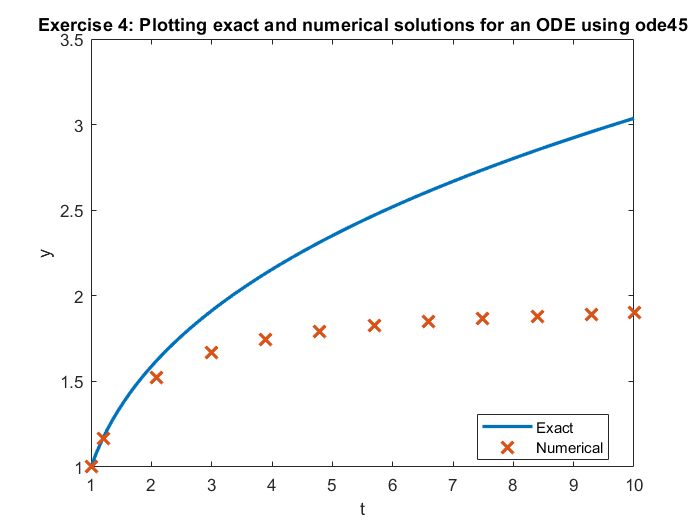

%Your axes should be appropriately labeled and include a legend.

f = @(y,t) 1/(y.^2);

%Parameters
t0 = 1;
t1 = 10;
y0 = 1;

%ODE45 solution:
soln4 = ode45(f, [t0, t1], y0);

%Exact solution:
x = linspace(t0, t1, 100);
y = (3*x - 2).^(1/3);

%Plot:
plot(x, y, soln4.x, soln4.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
title('Exercise 4: Plotting exact and numerical solutions for an ODE using ode45');
xlabel('t');
ylabel('y');
legend('Exact', 'Numerical', 'Location', 'Best');


%Compute max error:
yexact  = (3*soln4.x - 2).^(1/3);
fprintf('Max error is: %g \n', max(abs(yexact - soln4.y)));

Max error is: 1.13653 


## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

from `t=0` to `t=10`. 

Your solution should show you defining the inline function, computing the solution in this interval, and plotting it.

Your axes should be appropriately labeled

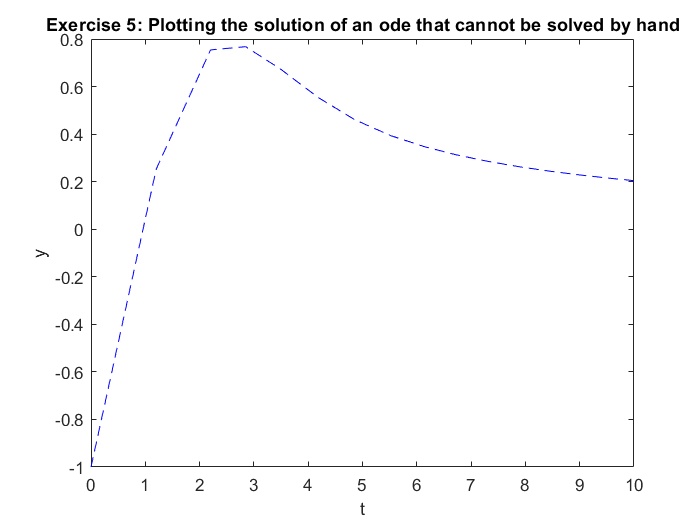

f = @(t,y) 1 - t*y/2 ; 

%Parameters:
t0 = 0;
t1 = 10;
y0 = -1;

%solution: 
soln  = ode45(f, [t0, t1], y0);

plot(soln.x, soln.y, 'b', 'Linestyle', '--');
title('Exercise 5: Plotting the solution of an ode that cannot be solved by hand');
xlabel('t');
ylabel('y');

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

from `t=0` to `t=1`. 

Your solution should show you defining the inline function, and computing the solution in this interval.

If you try to plot the solution, you should find that the solution does not make it all the way to t = 1.

In the comments explain why MATLAB generates the warning message that you may see, or fails to integrate all the way to t=1. HINT: Try plotting the direction field for this with IODE.

f = @(t,y) y.^3 - t.^2;

%Parameters:
y0 = 1;
t0 = 0;
t1 = 1;

%Solution:
soln = ode45(f, [t0,t1], y0);

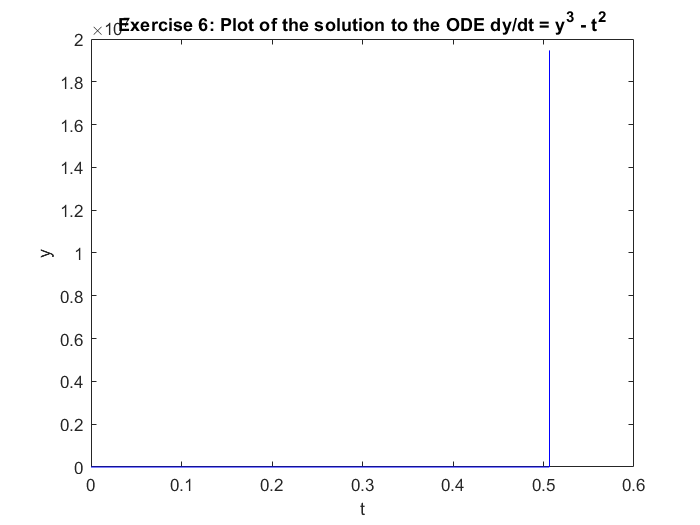


plot(soln.x, soln.y, 'b');
title('Exercise 6: Plot of the solution to the ODE dy/dt = y^3 - t^2');
xlabel('t');
ylabel('y');

## Solution Continued:

When we plot the direction field in iode for the above differential equation, we obtain:

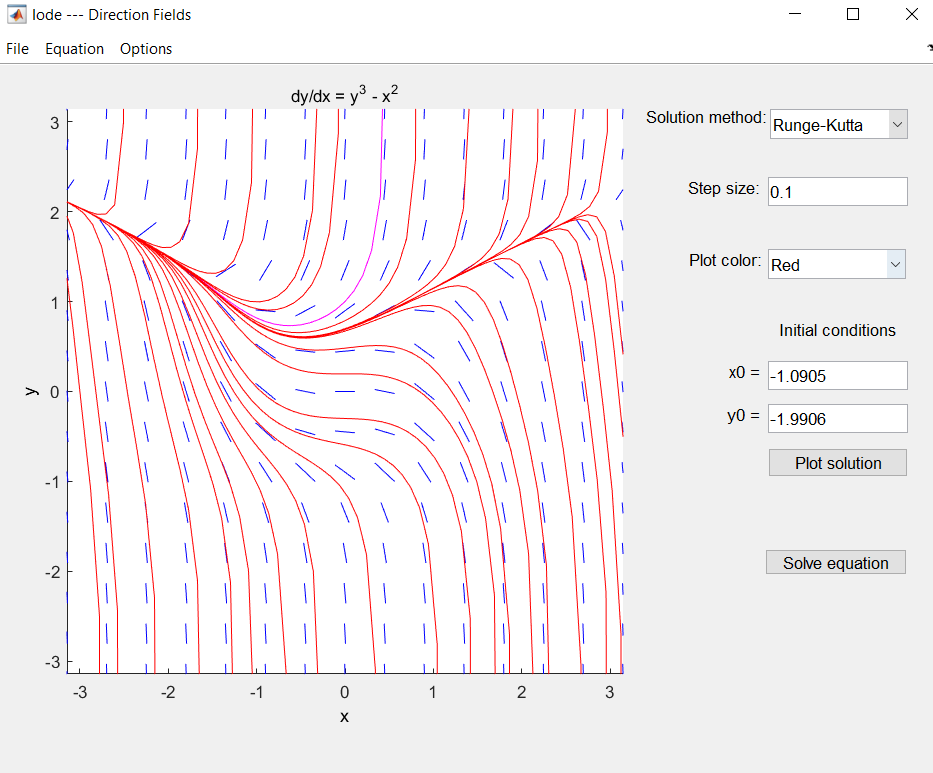

The Magenta line shows the behaviour of the solution given the specific initial conditions y0 = 0. We can see that there is some sort of asymptotal behaviour of the solution, thus preventing it to reach to t = 1. 

## Using symbolic variables to define functions

We can define symbolic variables to let MATLAB know that these variables will be used for exact computations

% Start by defining the variables as symbolic
syms t s x y

% Define a function by simply writing its expression

f = cos(t)

$$f = \cos\left(t\right)$$

g = sin(t)

$$g = \sin\left(t\right)$$

h = exp(2*x)

$$h = {\mathrm{e}}^{2\,x}$$


% We can manipulate these functions

simplify(f^2+g^2)

$$ans = 1$$

diff(h)

$$ans = 2\,{\mathrm{e}}^{2\,x}$$

int(h)

$$ans = \frac{{\mathrm{e}}^{2\,x}}{2}$$

% We can plot a function defined symbolically using the command |ezplot|.
% Learn about the command |ezplot|:

help ezplot

 ezplot   (NOT RECOMMENDED) Easy to use function plotter
 
  ezplot is not recommended. Use FPLOT or FIMPLICIT instead.
 
    ezplot(FUN) plots the function FUN(X) over the default domain
    -2*PI < X < 2*PI, where FUN(X) is an explicitly defined function of X.
 
    ezplot(FUN2) plots the implicitly defined function FUN2(X,Y) = 0 over
    the default domain -2*PI < X < 2*PI and -2*PI < Y < 2*PI.
 
    ezplot(FUN,[A,B]) plots FUN(X) over A < X < B.
    ezplot(FUN2,[A,B]) plots FUN2(X,Y) = 0 over A < X < B and A < Y < B.
 
    ezplot(FUN2,[XMIN,XMAX,YMIN,YMAX]) plots FUN2(X,Y) = 0 over
    XMIN < X < XMAX and YMIN < Y < YMAX.
 
    ezplot(FUNX,FUNY) plots the parametrically defined planar curve FUNX(T)
    and FUNY(T) over the defau

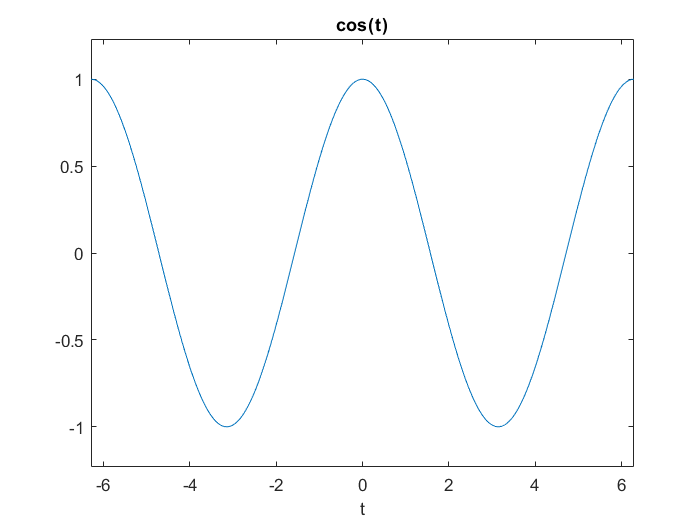


% Plot the function |f(t)| and |h(x)|

ezplot(f)

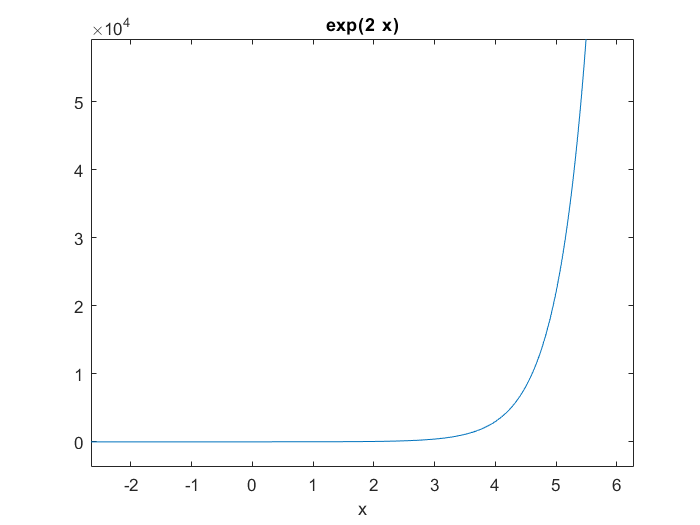

ezplot(h)

If we try to evaluate the function `f(0)`, we get an error message. 

The symbolic variables are not meant to be used to evaluate functions, but to manipulate functions, compute derivatives, etc. To evaluate a function using symbolic variables is a little cumbersome:

% We need to substitute the variable by a value:

subs(f,t,pi)

$$ans = -1$$

This expression means: In the expression `f`, substitute the variable `t` by the number `pi`.

% If we use a value where the cosine does not have a "nice" expression, we
% need to approximate the result:

subs(f,t,2)

$$ans = \cos\left(2\right)$$


% We need to use the command |eval|

eval(subs(f,t,2))

ans = -0.4161

## Exercise 7

Objective: Define a function using symbolic variables and manipulate it.

Details: Define the function `f(x) = sin(x)cos(x)`

Use MATLAB commands to obtain a simpler form of this function, compute value of this function for `x=pi/4` and `x=1`, and plot its graph.

syms x;
f = cos(x)*sin(x)

$$f = \cos\left(x\right)\,\sin\left(x\right)$$

simplify(f)

$$ans = \frac{\sin\left(2\,x\right)}{2}$$

eval(subs(f, x, (pi/4)))

ans = 0.5000

eval(subs(f, x, 1))

ans = 0.4546

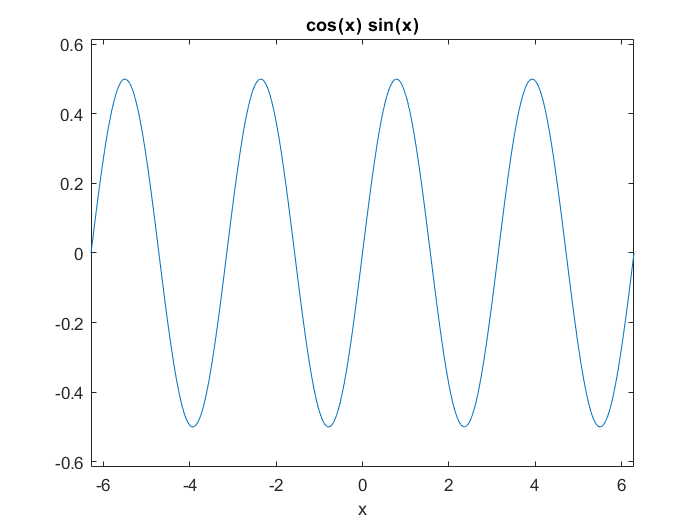

ezplot(f)

## Obtaining Picard approximations

Consider an initial value problem

`y' = 1 + y` , `y(0) = 0`

First we need to define the variables we will be using

syms t s y;

% We then need to define the function f

f = 1+y; % we define it without the @(t,y) because it is a symbolic function

% We set up our initial approximation phi_0 = 0:

phi=[sym(0)];   % we will keep a list with all the approximations

% Set up a loop to get successive approximations using Picard iterations

N=5;

for i = 1:N
    func=subs(f,y,phi(i));    % prepare function to integrate: y -> previous phi
    func=subs(func,t,s);      % variable of integration is s, so we need to change
                              % t -> s
    
    newphi = int(func, s, 0 ,t);   % integrate to find next approximation
    
    phi=cat(2,phi,[newphi]);       % update the list of approximations by adding new phi -->    %cat(DIM,A,B) concatenates the arrays A and B along
end                                                                                             % the dimension DIM.  
                                                                                                % cat(2,A,B) is the same as [A,B].
                                                                                                % cat(1,A,B) is the same as [A;B].

% Show the last approximation

phi(N+1)

$$ans = \frac{t\,\left(t^{4}+5\,t^{3}+20\,t^{2}+60\,t+120\right)}{120}$$

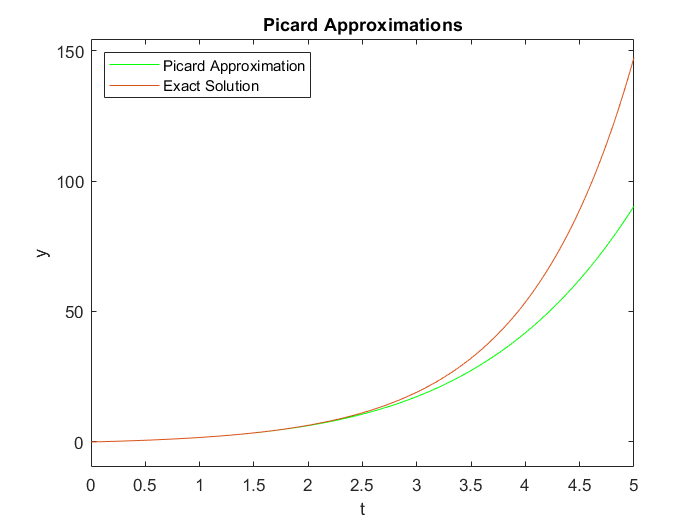


% Plot the approximation just found

picard=ezplot(phi(N+1),[0,5]);      % plot from t = 0 to t = 5
set(picard,'Color','green');         % set the color of the graph to green

% In this case, the exact solution is
%
% |y=e^t-1|
%
% Compare the approximation and the exact solutions

hold on;
exact=ezplot(exp(t)-1,[0,5]);

xlabel('t');
ylabel('y');
title('Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');
hold off;

## Exercise 8

Find the Picard approximation phi_5. For better efficiency, do not keep all the previous approximations.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Label your axes and include a legend.

HINT. The initial condition has 1 instead of 0, so the Picard method needs to be adapted.

syms t y s;

% Exact solution:
%yexact = tan(t + (pi/4));

f8 = 1 + y.^2;

phi8 = sym(1);           %Intial condition is y(0) = 1

N = 5;

for i = 1:N
    func8 = subs(f8,y,phi8);    % prepare function to integrate: y -> previous phi
    func8 = subs(func8,t,s);      % variable of integration is s, so we need to change
                              % t -> s
    
    newphi8 = int(func8, s, 0 ,t) + 1;   % integrate to find next approximation
    
    phi8 = newphi8;       % update the list of approximations by adding new phi -->    %cat(DIM,A,B) concatenates the arrays A and B along
end                                                                                             % the dimension DIM.  
                                                                                                % cat(2,A,B) is the same as [A,B].
                                                                                                % cat(1,A,B) is the same as [A;B].

% Show the last approximation
phi8

$$phi8 = \frac{65536\,t^{31}}{109876902975}+\frac{32768\,t^{30}}{3544416225}+\frac{33636352\,t^{29}}{445414972275}+\frac{2189312\,t^{28}}{5119712325}+\frac{3771621376\,t^{27}}{2017062172125}+\frac{3496164352\,t^{26}}{522942044625}+\frac{1852466944\,t^{25}}{91423434375}+\frac{28632512\,t^{24}}{536350815}+\frac{234841821952\,t^{23}}{1884677169375}+\frac{14839805056\,t^{22}}{56729413125}+\frac{1241511104\,t^{21}}{2483105625}+\frac{400722032\,t^{20}}{456080625}+\frac{1157035136\,t^{19}}{808782975}+\frac{4159073344\,t^{18}}{1915538625}+\frac{1240970116\,t^{17}}{402026625}+\frac{175768612\,t^{16}}{42567525}+\frac{1111144976\,t^{15}}{212837625}+\frac{29636504\,t^{14}}{4729725}+\frac{4842328\,t^{13}}{675675}+\frac{1221016\,t^{12}}{155925}+\frac{425608\,t^{11}}{51975}+\frac{1108\,t^{10}}{135}+\frac{22376\,t^{9}}{2835}+\frac{764\,t^{8}}{105}+\frac{32\,t^{7}}{5}+\frac{16\,t^{6}}{3}+\frac{64\,t^{5}}{15}+\frac{10\,t^{4}}{3}+\frac{8\,t^{3}}{3}+2\,t^{2}+2\,t+1$$

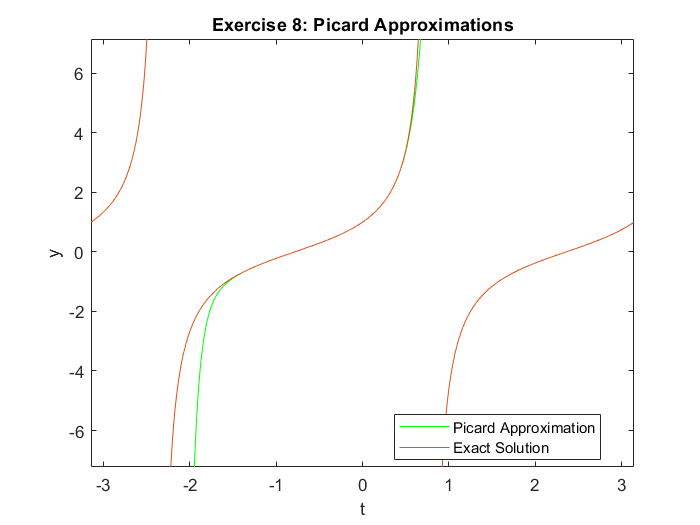



% Plot the approximation just found

picard8 = ezplot(phi8,[-pi,pi]);      % plot from t = 0 to t = 5
set(picard8,'Color','green');         % set the color of the graph to green


% Compare the approximation and the exact solutions

hold on;
exact8 = ezplot(tan(t + (pi/4)),[-pi,pi]);

xlabel('t');
ylabel('y');
title('Exercise 8: Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','best');
hold off;